#### CREAMOS SUPERFICIE DE CONO 

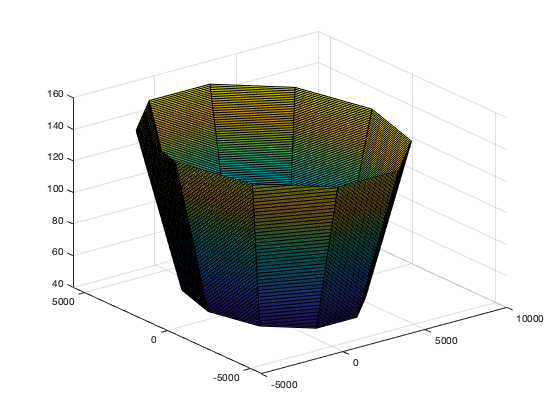


% 
h = 0:1:100;
r = 20*h+4000; %radio va de 4000 a 6000
[x,y,z]=cylinder(r,10);
z= 100*z+45; % el 100* es para rescalarlo de 0 a 1 A  0 a 100, y els 45 para subir. 
x = x+logitudPista/2; % centramos en cono en pista
h = surf(x,y,z);


A = [h.XData(:),h.YData(:),h.ZData(:)];
h_alturas = 45:10:145;

kw = 2000;

for i = 1:1:length(h_alturas)
    
    last = length(A);

    A(last+1,1) = logitudPista/2+kw;
    A(last+1,2) = kw;    
    A(last+1,3) = h_alturas(i);
    
    A(last+2,1) = logitudPista/2-kw;
    A(last+2,2) = kw;    
    A(last+2,3) = h_alturas(i);
    
    A(last+3,1) = logitudPista/2-kw;
    A(last+3,2) = -kw;    
    A(last+3,3) = h_alturas(i);
    
    A(last+4,1) = logitudPista/2+kw;
    A(last+4,2) = -kw;    
    A(last+4,3) = h_alturas(i);
    
    A(last+5,1) = logitudPista/2;
    A(last+5,2) = 0;    
    A(last+5,3) = h_alturas(i);
    
    
end
 
FiguraCono = alphaShape(A(:,1), A(:,2),A(:,3)*10);

#### MIRAR SI ESTA EN SUPERCICIE CONO


EstaEnCONO = inShape(FiguraCono,xyz)

EstaEnCONO = 5×1 logical array
   0
   0
   0
   0
   0


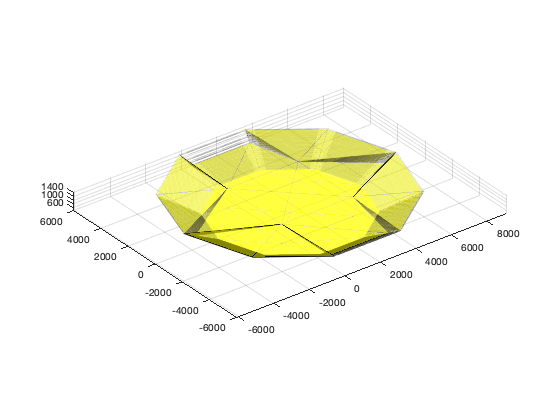

plot(FiguraCono,'FaceColor','yellow','FaceAlpha',0.5,"EdgeAlpha",0.05);%plot de cono